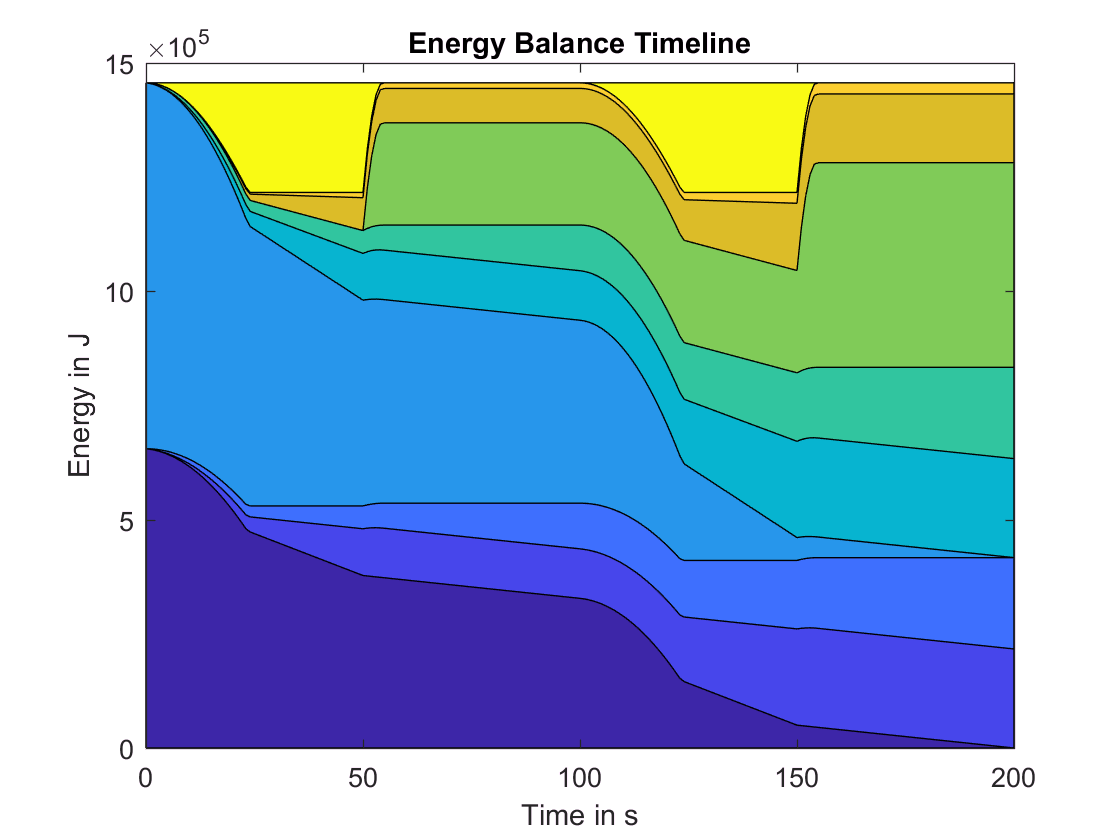

n = logsout.numElements;
ts = logsout{1}.Values.Time;
res = zeros(length(ts),n);
for i=1:n
    E = logsout{i}.Values.Data;
    E = E(:,1);
    res(:,i) = E - min(E);
end
area(ts,res);
xlabel('Time in s');
ylabel('Energy in J');
title('Energy Balance Timeline');